## Interpolazione

In questa demo confrontiamo diversi tipi d'interpolazione

- Interpolazione effettuata dalla scheda audio (tipicamente, sinc troncato)

- Interpolazione sample and hold (ordine zero)

- Interpolazione lineare (ordine 1)

- Interpolazione cubica (ordine 3)

Come nella demo sul sottocampionamento, partiamo da un segnale campionato a $F_c$=16kHz, poi lo sottocampioniamo ed infine lo interpoliamo usando i diversi metodi. 

Premere `F5` per eseguire tutta la demo, oppure premere `CTRL+ENTER` per eseguire la sezione corrente. 

#### Inizializzazioni

Cancelliamo tutte le variabili in memoria e chiudiamo eventuali figure

clear variables
close all

#### Caricamento

Qui si carica e si ascolta la traccia audio. Se si vuole registrare una nuova traccia, usare `recordVoice.mlx`

namefile='myvoicerecording16kHz.mat';
load(namefile,'Fc','y','N')
% Periodo di campionamento
Tc = 1/Fc;
% numero di campioni nella traccia
M = length(y);
% intervallo temporale della traccia
t =(0:M-1)*Tc;

% Riproduzione della traccia audio registrata
h=msgbox('Segnale vocale'); 
yp=audioplayer(y,Fc);
play(yp)
waitfor(h);

#### Ricampionamento

Viene conservando un campione ogni  $K$, per cui la nuova frequenza di campionamento è $f_{\mathrm{New}} =\frac{f_c }{K}$

Effettuiamo prima il filtraggio anti aliasing, perché qui vogliamo solo studiare l'effetto dell'interpolazione. Ovviamente, la frequenza di taglio del filtro dipende da $f_{\mathrm{New}}$

K = 4;
fNew = Fc/K; 

Fnorm = fNew/Fc; %  frequenza di taglio normalizzata
df = designfilt('lowpassfir','FilterOrder',400,'CutoffFrequency',Fnorm);
D= 200; % 
yLP = filter(df,[y; zeros(D,1)]);
yLP = yLP(D+1:end);                  % Spostamento dei dati per compensare il ritardo

mysampling=@(y,step) y(1:K:end);
% Calcolo della versione sottocampionata del vettore di ingresso
ysLP = mysampling(yLP,K);
% vettore dei tempi corrispondente
ts = mysampling(t,K);

Ora, quando eseguiamo la lettura di tale segnale sottocampionato, stiamo chiedendo alla scheda audio di *creare* per noi i valori mancanti, usando un'opportuna interpolazione. Tipicamente una scheda audio usa un $\mathrm{sinc}$ troncato.  

h2=msgbox(['Interp. sched audio, Fc =',num2str(fNew/1e3),' kHz']);
ysp=audioplayer(ysLP,fNew);
play(ysp);
waitfor(h2);

### Uso di diversi kernel d'interpolazione

Matlab implementa i tre kernel polinomiali tramite la funzione `interp1`

kernel='linear';
yInterp = interp1(ts,ysLP,t,kernel);

h3=msgbox(['Interp. ', kernel, ', Fc =',num2str(fNew/1e3),' kHz']);
yIntP=audioplayer(yInterp,Fc);
play(yIntP);
waitfor(h3);

Visualizziamo il segnale interpolato. Come al solito usiamo uno zoom per vedere bene l'andamento

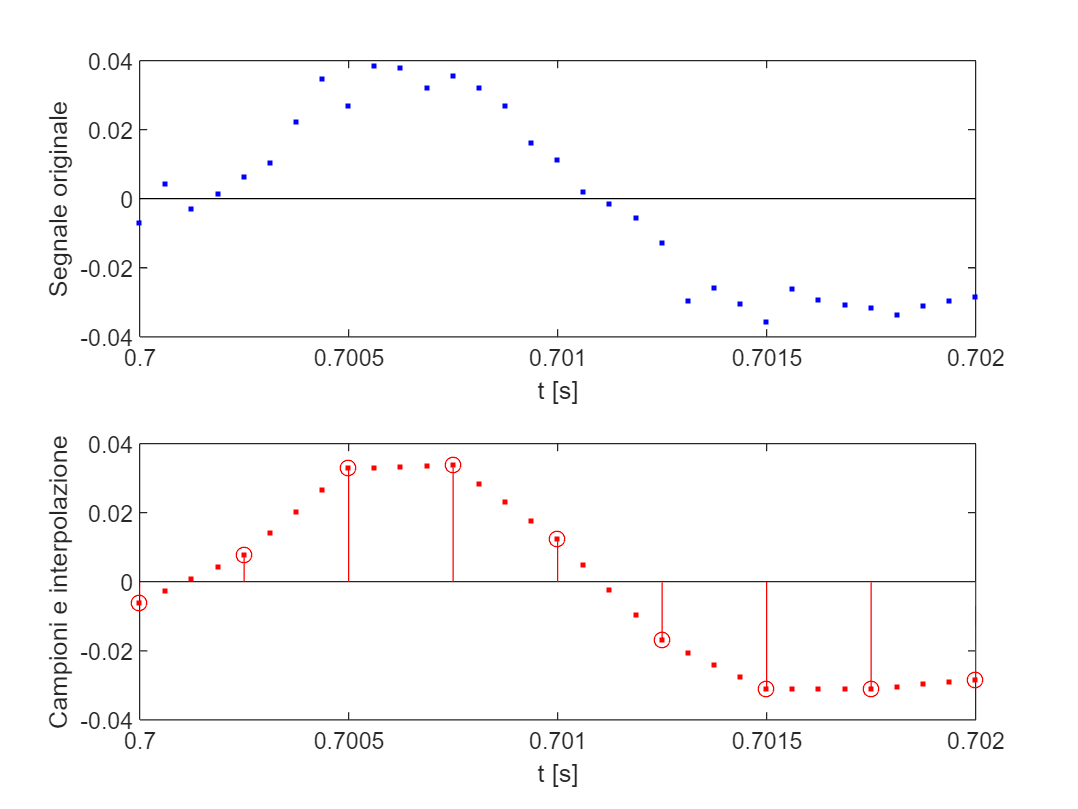

figure
tStart = 0.7; duration = 2e-3; 
subplot(2,1,1)
plot(t,y,'b.');
line([tStart, tStart+duration], [0 0], color='black'); %disegna asse x
xlim([tStart,tStart+duration]) %% Qui facciamo lo zoom
xlabel('t [s]')
ylabel('Segnale originale')
subplot(2,1,2)
h=stem(ts,ysLP,'r'); hold on;
plot(t,yInterp, 'r.')
xlim([tStart,tStart+duration]) %% Lo stesso qui
xlabel('t [s]')
ylabel('Campioni e interpolazione');

Adesso visualizziamo gli spettri

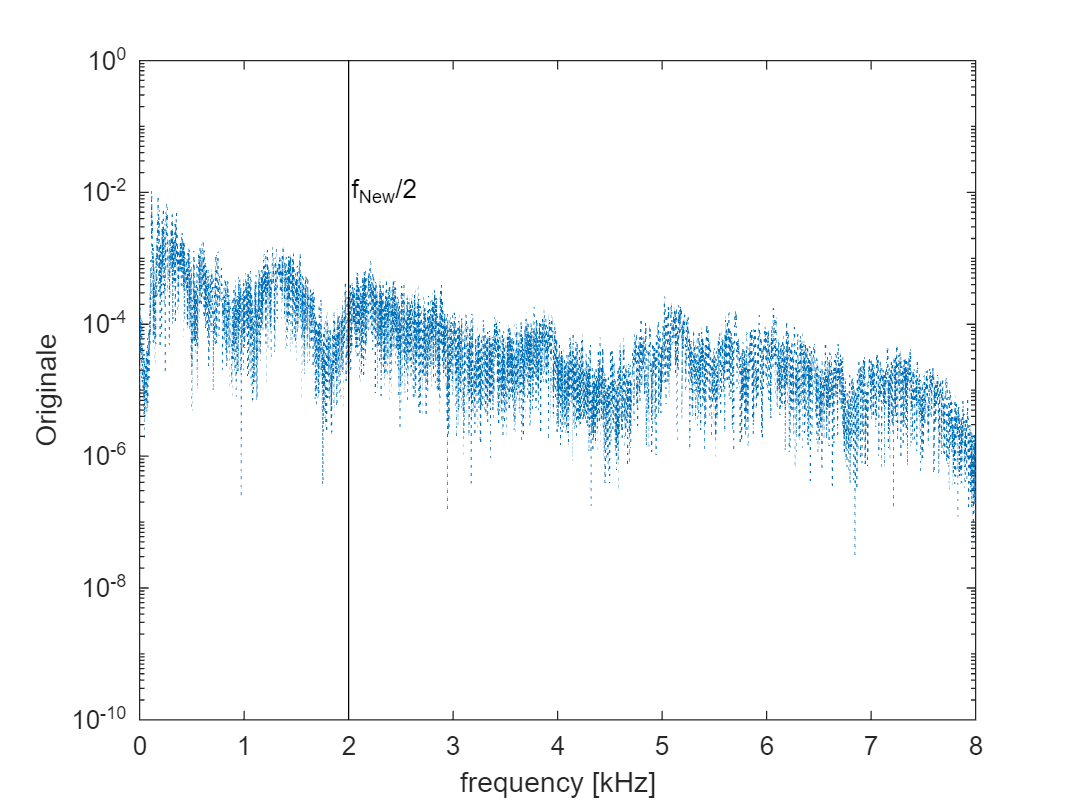

[Y,F ] = CTFT_real(y,Fc);
[YSLP, FS ] = CTFT_real(ysLP,fNew);
[YINTERP, FI ] = CTFT_real(yInterp,Fc);

figure
semilogy(F/1e3, Y, ':'); hold on
text(fNew/2e3,0.01,'f_{New}/2');
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  
xlabel('frequency [kHz]')
ylabel('Originale')

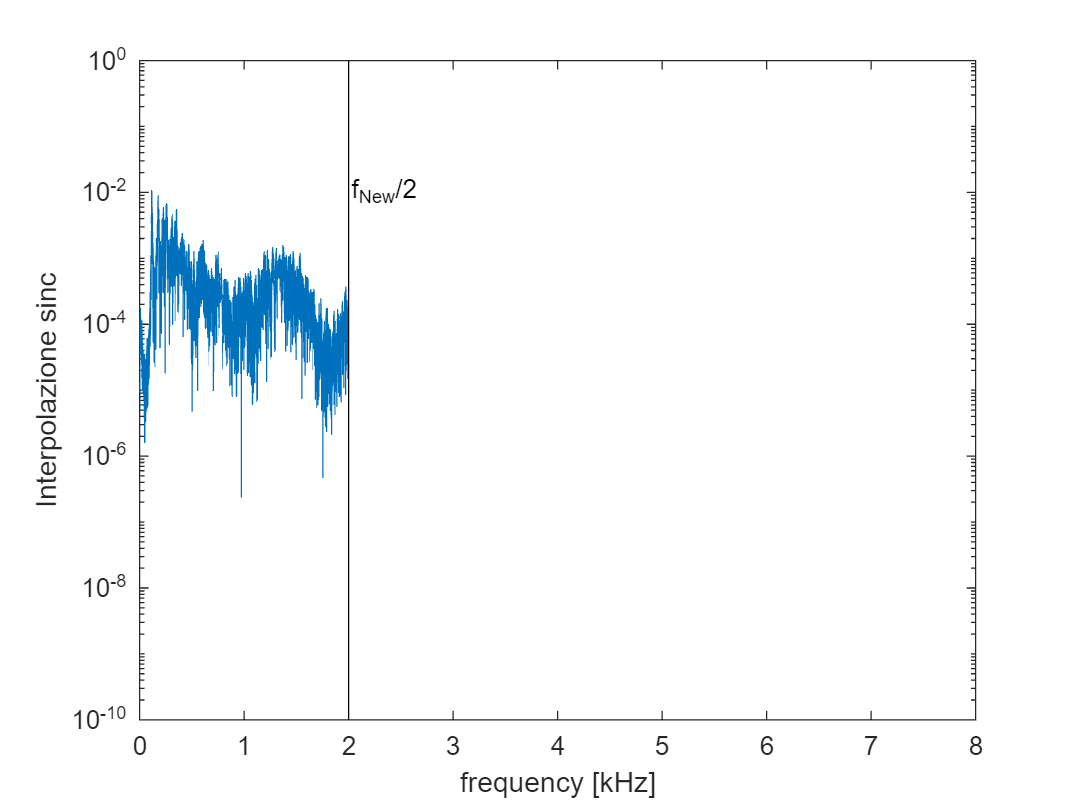

figure
semilogy(FS/1e3,YSLP,'color',"#0072BD");text(fNew/2e3,0.01,'f_{New}/2');
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  
ylim([1e-10,1])
ylabel('Interpolazione sinc')
xlabel('frequency [kHz]')
xlim([min(F/1e3),max(F/1e3)])
ylim([1e-10,1])

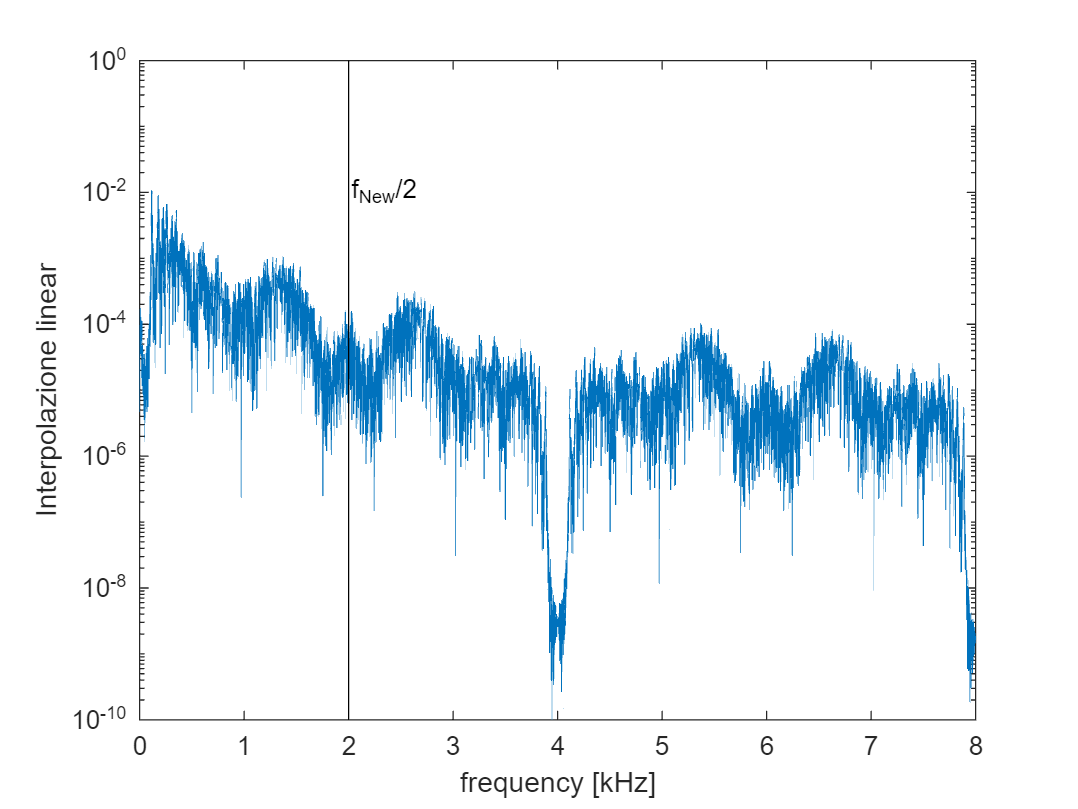

figure
semilogy(FI/1e3,YINTERP,'color',"#0072BD");text(fNew/2e3,0.01,'f_{New}/2');
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  
ylim([1e-10,1])
ylabel(['Interpolazione ', kernel])
xlabel('frequency [kHz]')
xlim([min(F/1e3),max(F/1e3)])

La pseudo-periodicità che si osserva nello spettro del segnale interpolato deriva dal sottocampionamento iniziale a frequenza $f_{\mathrm{New}}$